# Project 2

*Authors:* Dakota Chang and Kenneth Xiong

*Last Updated: *November 4, 2023

*Summary: *This computational essay serves as the ModSim 23-24 Fall Term Project 2, focusing on the modeling query: 'How does class size influence disease spread within a student population?' Employing an agent-based model and a complete graph featuring pods of various sizes and weights, we aim to address this question. The notebook is structured into four main sections: Question, Methodology, Results, and Interpretation.

## Question:

### Background Information + References:

Since the COVID-19 pandemic, schools have been interested in studying the nature of disease transmission in their classrooms. Schools were beginning to open their doors to in-person learning and needed to understand how that would affect the transmission of COVID-19 (Hekmati). They found that there was very little research on the behavior of infectious diseases and what preventive measures would be most effective(COVID-19 Working Group). When there was information about disease transmission, it was based on assumptions(like how class size affects transmission) that might have led to biased results(COVID-19 Working Group). 

### Importance/Interest:

Because of this, this essay seeks to explain how different class sizes affect disease spread within a given population.

Question: How does class size influence disease spread within a student population?

### Modeling Question and Categorization:

Not only is understanding this important for preventing future pandemics, but it’s also important for stemming the spread of other diseases that thrive in school environments like influenza(Endo et al.).

Research Synthesis Matrix: [https://docs.google.com/spreadsheets/d/1kzDWpNepGnaOVogJqf5ZUqgpej4O49TwtW78Yk4wx2U/edit?usp=sharing](https://docs.google.com/spreadsheets/d/1kzDWpNepGnaOVogJqf5ZUqgpej4O49TwtW78Yk4wx2U/edit?usp=sharing)

## METHODOLOGY

**Model:**

To best capture the dynamics of the social network within a school, we've opted for a "leaky pod" agent-based model. In this model, each pod corresponds to a specific class. The strength of connections between individual agents within a pod is determined by class size, with smaller classes resulting in more robust connections. We've chosen to represent this relationship using a ratio of ####. 

Additionally, our model is designed as a complete graph to simulate the comprehensive interconnections characteristic of a school's social network. However, it's important to note that these connections are intentionally configured to be relatively weak in nature.

**Assumptions:**

We hypothesize that smaller class sizes foster stronger connections among students within a particular class. This hypothesis is grounded in the observation that larger classes typically adopt a lecture-based format in extensive lecture halls, whereas smaller classes often emphasize interactive and team-based learning. These assumptions are reasonable within the context of our model, which investigates the impact of class sizes and teaching styles on disease transmission. 

We also assume complete interconnectedness among all students might not hold true in larger colleges. Moreover, we've assumed equal connectivity among students within each class. Nevertheless, these specific assumptions might not be directly pertinent to our primary modeling objective, which primarily focuses on the effects of class size and teaching methodologies on disease spread rather than providing a precise estimation of disease transmission rates.

We also assume that class sizes are the same for all classes. While this might be accurate for smaller institutions, this does not hold for larger institutions where large lecture-format classes only account for a small percent of the total classes. We feel that the impact of this assumption varies based on year of college students are in. Freshman might have only large classes, while senior won't have any.

Demonstration of function "create_classes."

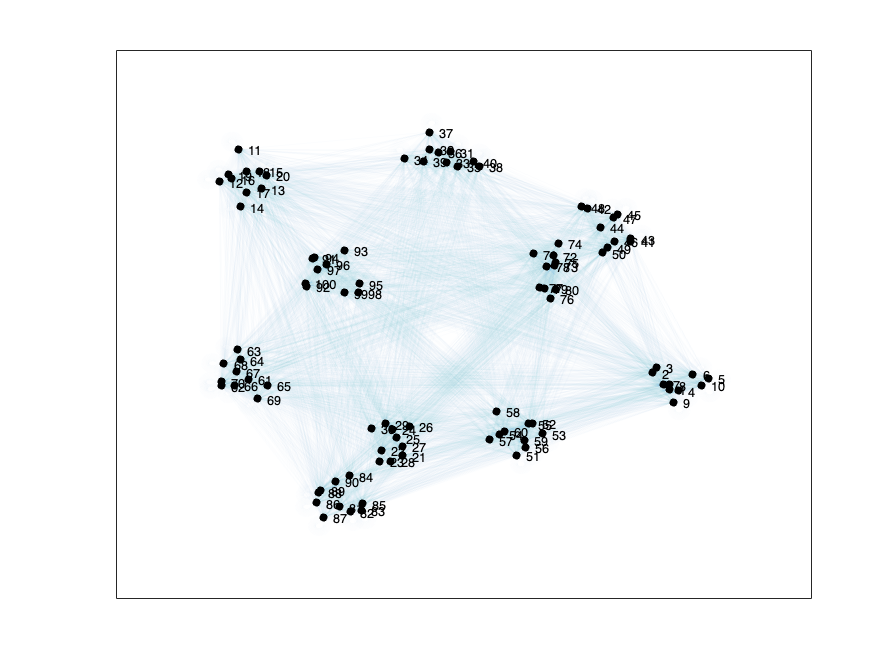

total_pop = 100; 
class_size = 10;
weight = total_pop/class_size;
create_classes(total_pop, class_size, weight);

Here is the code to conduct three distinct simulations across 150 time steps. One simulation focuses on small class sizes, assuming 10 students per class. The second simulation involves medium class sizes, with an assumed count of 50 students per class. The third simulation pertains to large class sizes, where an assumed count of 100 students per class is utilized. The total school population is set at 1000 individuals. As previously highlighted, these assumptions are designed not to significantly impact the ultimate results, as our primary aim is to observe trends rather than precisely predict disease spread rates.

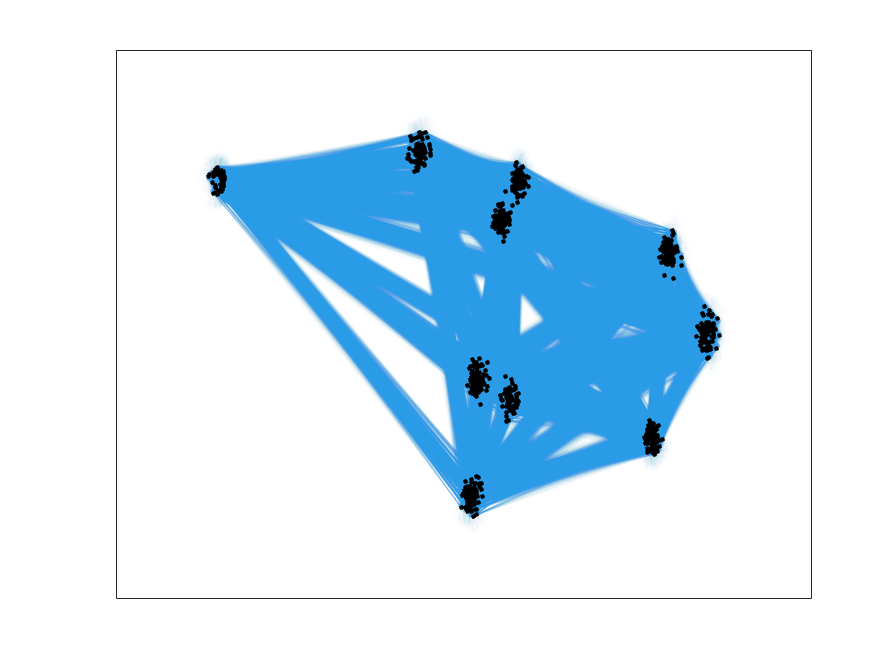

total_pop = 1000;

% creates complete graph overlaid by leaky pod graph to calibrate connection weights 
[M_small, plot_small] = create_classes(total_pop , 100, total_pop /10); % small class

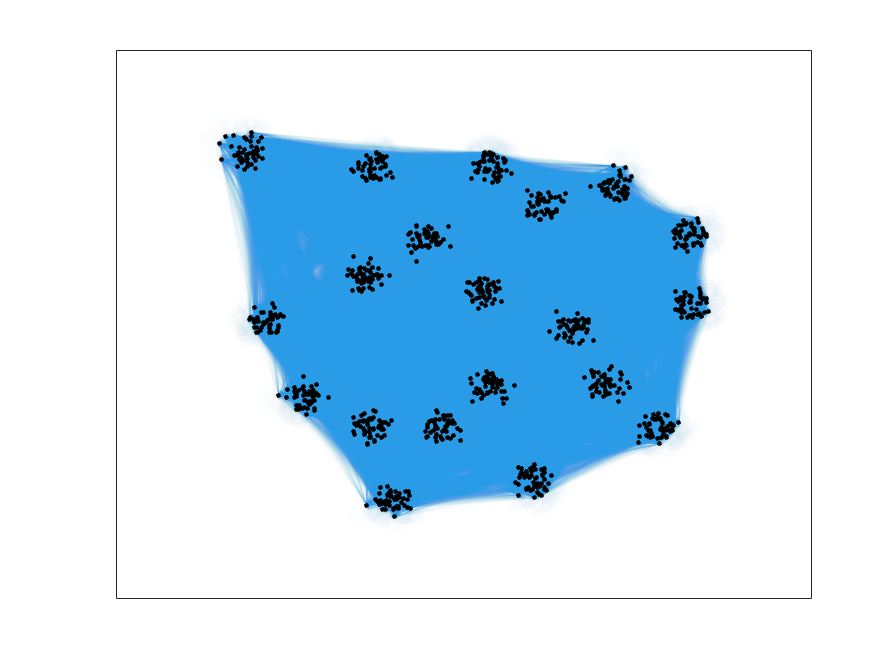

[M_medium, plot_medium] = create_classes(total_pop , 50, total_pop /50); % medium class

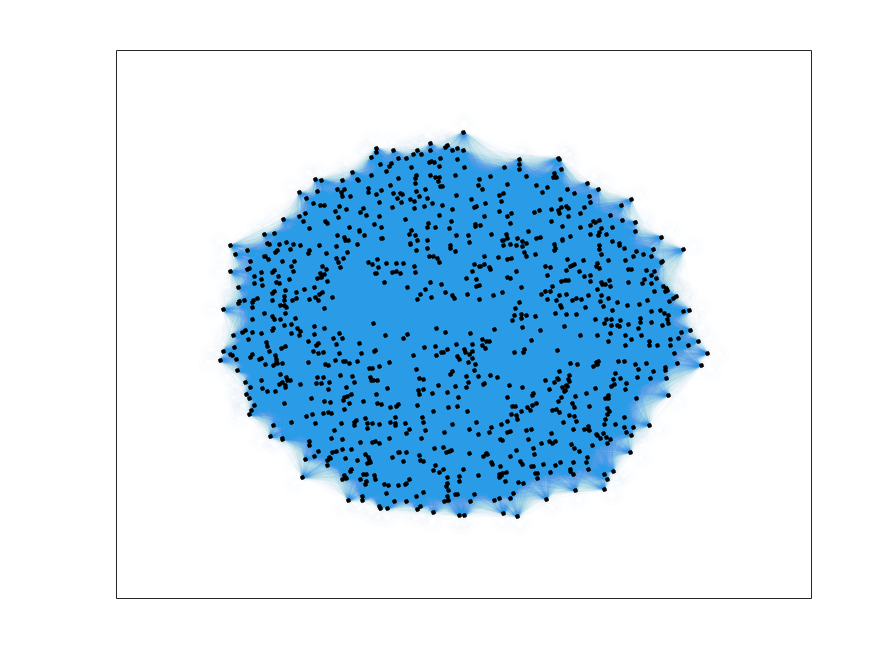

[M_big, plot_big] = create_classes(total_pop , 10, total_pop /100); % big class

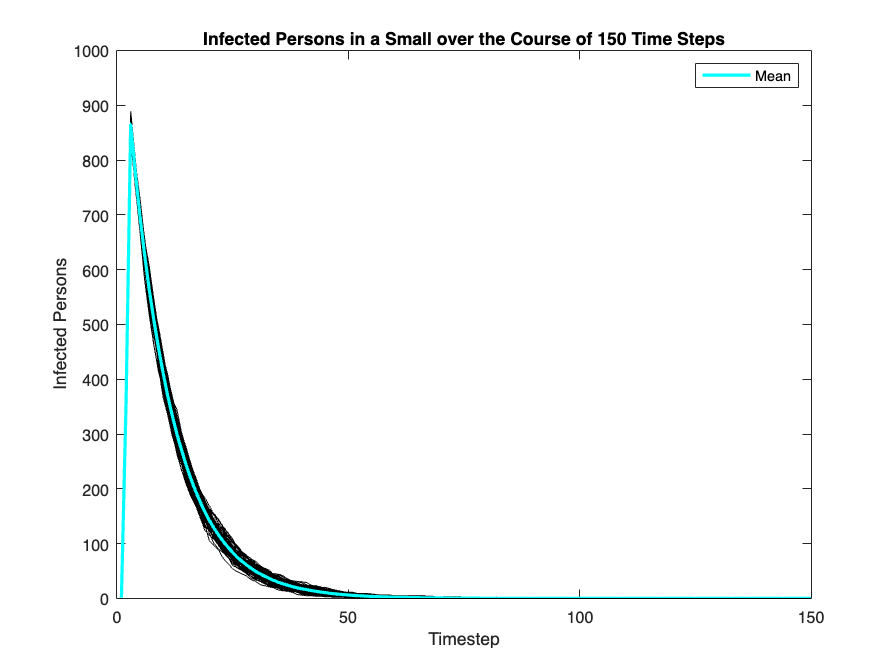


% matrix of same size to store infected persons per time step,
% matrix starts with one as we assume one student to be patient #0.
Iv1 = zeros(total_pop , 1);
Iv1(1) = 1;

% infection and recovery rate
infection_rate = 0.5; recovery_rate = 0.1;

% Set the number of replications for the agent-based model
n_realizations = 100;

%time to run
T_simulation = 150;

% Reserve space for simulation results
Is_ensemble = zeros(T_simulation, n_realizations);
Im_ensemble = zeros(T_simulation, n_realizations);
Ib_ensemble = zeros(T_simulation, n_realizations);
%Space for maxes
Is_max = zeros(1, n_realizations);
Im_max = zeros(1, n_realizations);
Ib_max = zeros(1, n_realizations);


% Set the random seed. This is something we'll talk about in the next
% module.
rng(101)

% simulation of disease spread in constructed models
for i = 1 : n_realizations
    [Ss, Is, Rs] = simulate_absir(M_small, Iv1, T_simulation, infection_rate, recovery_rate);
    [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, T_simulation, infection_rate, recovery_rate);
    [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, T_simulation, infection_rate, recovery_rate);
    Is_ensemble(:, i) = sum(Is, 1);
    Im_ensemble(:, i) = sum(Im, 1);
    Ib_ensemble(:, i) = sum(Ib, 1);
    Is_max(i) = max(sum(Is, 1));
    Im_max(i) = max(sum(Im, 1));
    Ib_max(i) = max(sum(Ib, 1));
end
%calc the mean
Is_mean = mean(Is_ensemble, 2);
Im_mean = mean(Im_ensemble, 2);
Ib_mean = mean(Ib_ensemble, 2);



%verification facts
%make sure agent is only in one state at a time
assert(sum(all(Ss+Is+Rs==1))==150)
%make sure an agent isn't in a fracitonal state(checking if rounding down
%in the matrix creates a matrix than is different from the original
assert(sum(all(floor(Ss) ~= Ss,'all')) == 0)
assert(sum(all(floor(Rs) ~= Rs,'all')) == 0)
assert(sum(all(floor(Is) ~= Is,'all')) == 0)

% Visualize
figure()
plot(Is_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(Is_mean, 'c-', 'LineWidth', 2.0, 'DisplayName', 'Mean');
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 1000])
legend()
legend()
title("Infected Persons in a Small Class over the Course of 150 Time Steps")
xlabel('Timestep')
ylabel('Infected Persons')

*TODO:*

*Development*

- How did you set the parameters of your model?

- What verification facts did you come up with for your model? What assert() statements did you use to implement your verification facts?

- Your assert() statements must appear in your computational essay

Parameter Sweep For Different Class Sizes

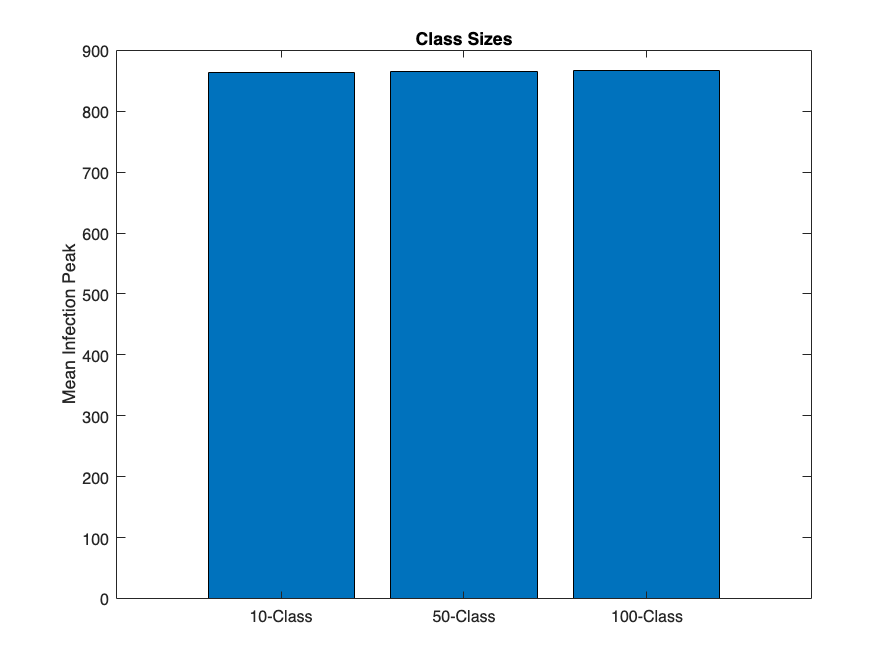

I_max_data = [
    Is_max;
    Im_max;
    Ib_max
];
X = categorical({'10-Class', '50-Class', '100-Class'});
X = reordercats(X, {'10-Class', '50-Class', '100-Class'});

figure(); clf;
bar(X, mean(I_max_data, 2))
ylabel('Mean Infection Peak')
title('Class Sizes')

Parameter Sweep (Infection Rate)

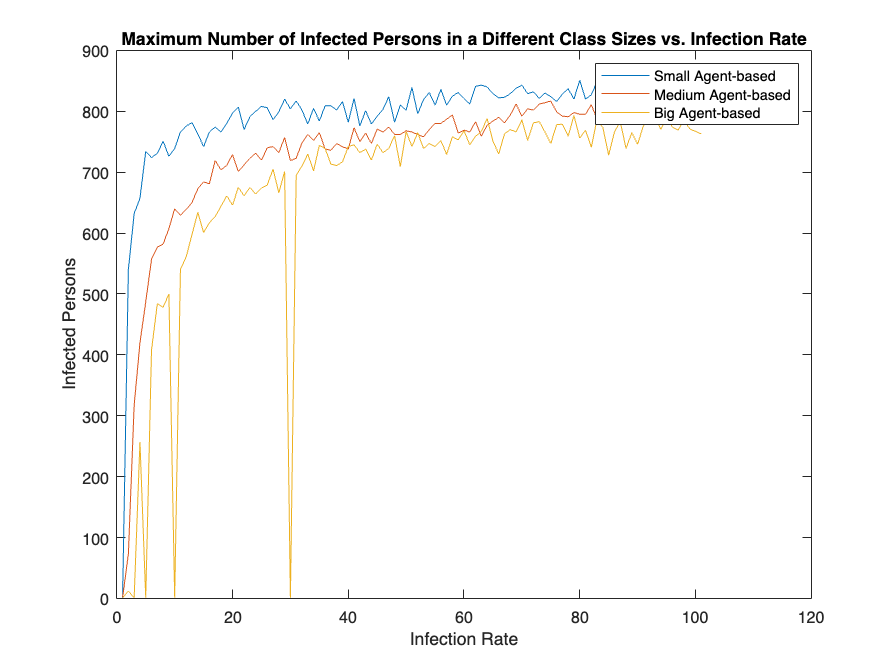

% parameter sweep for infection rate:
infection_rate = 0:0.0001:0.01;
recovery_rate = 0.1;
Is_peak = zeros(1, 100); Im_peak = zeros(1, 100); Ib_peak = zeros(1, 100);

for i = 1 : length(infection_rate)
    [Ss, Is, Rs] = simulate_absir(M_small, Iv1, 150, infection_rate(i), recovery_rate);
    [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, 150, infection_rate(i), recovery_rate);
    [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, 150, infection_rate(i), recovery_rate);

    Is_peak(i) = max(sum(Is));
    Im_peak(i) = max(sum(Im));
    Ib_peak(i) = max(sum(Ib));
end

figure()
plot(Is_peak, 'DisplayName', 'Small Agent-based'); hold on;
plot(Im_peak, 'DisplayName', 'Medium Agent-based');
plot(Ib_peak, 'DisplayName', 'Big Agent-based');
legend()
title("Maximum Number of Infected Persons in a Different Class Sizes vs. Infection Rate")
xlabel('Infection Rate')
ylabel('Infected Persons')

Parameter Sweep (Recovery Rate)

% parameter sweep for recovery rate:
infection_rate = 0.001;
recovery_rate = 0:0.01:1;
Is_peak = zeros(1, 100); Im_peak = zeros(1, 100); Ib_peak = zeros(1, 100);

for i = 1 : length(recovery_rate)
    [Ss, Is, Rs] = simulate_absir(M_small, Iv1, 150, infection_rate, recovery_rate(i));
    [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, 150, infection_rate, recovery_rate(i));
    [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, 150, infection_rate, recovery_rate(i));

    Is_peak(i) = max(sum(Is));
    Im_peak(i) = max(sum(Im));
    Ib_peak(i) = max(sum(Ib));
end

figure()
plot(Is_peak, 'DisplayName', 'Small Agent-based'); hold on;
plot(Im_peak, 'DisplayName', 'Medium Agent-based');
plot(Ib_peak, 'DisplayName', 'Big Agent-based');
legend()
title("Maximum Number of Infected Persons in a Different Class Sizes vs. Recovery Rate")
xlabel('Recovery Rate')
ylabel('Infected Persons')

Parameter Sweep (Class Size)

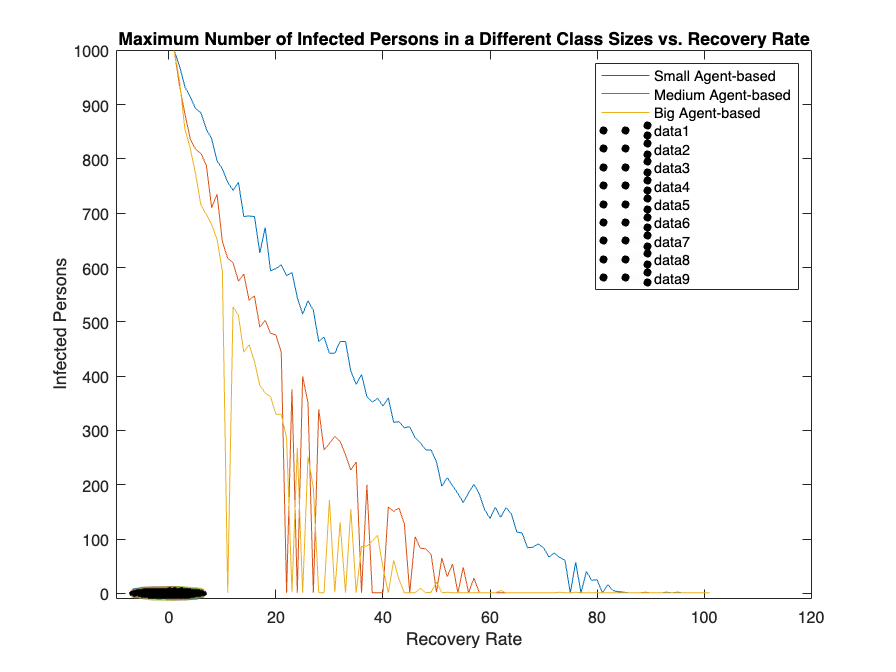

% parameter sweep for class size:
infection_rate = 0.001;
recovery_rate = 0.01;
I_peak = zeros(1, 9);
class_size = [1, 10, 20, 50, 100, 200, 250, 500, 1000];
class_size(1) = 1;

for i = 1 : length(class_size)
    [M, ~] = create_classes(total_pop , class_size(i), total_pop/class_size(i)); % small class
    [S, I, R] = simulate_absir(M, Iv1, 150, infection_rate, recovery_rate);
    I_peak(i) = max(sum(I));
end

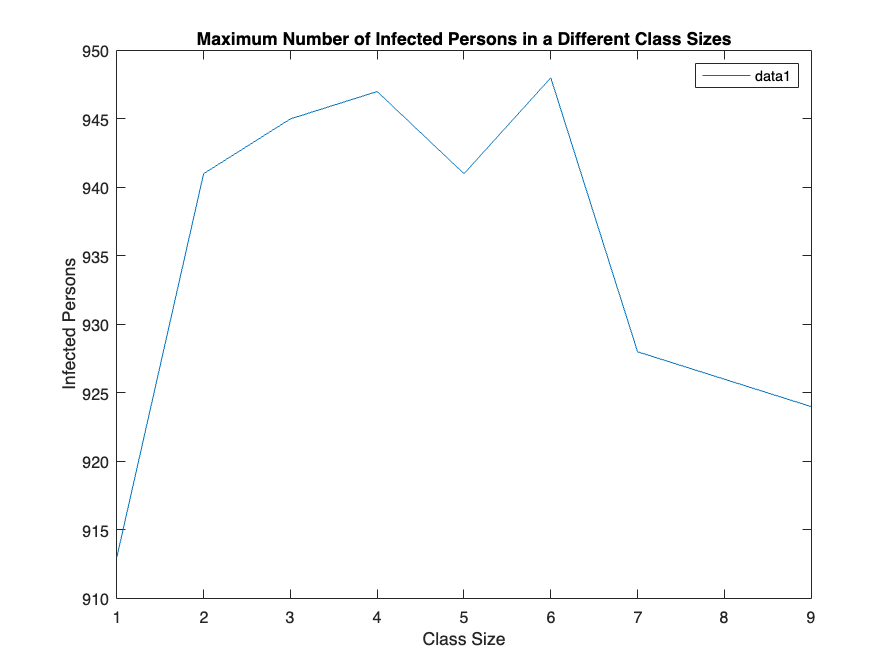


figure()
plot(I_peak); hold on;
legend()
title("Maximum Number of Infected Persons in a Different Class Sizes")
xlabel('Class Size')
ylabel('Infected Persons')

### Development:

Verification Facts: To verify that our model is correct, we checked two things: each agent isn’t in more than one state(i.e the value is greater than one), and agents aren’t in multiple fractional states.

### Validation:

*Within and between classroom transmission patterns of seasonal influenza among primary school students in Matsumoto city, Japan *details a similar trend with class sizes. They also found that class size had no significant impact on infections.

## Results

## Metrics and Sweeps:

We performed a parameter sweep across the different sizes of classes with the metric of mean infection peak. We felt that this was a good metric because it accurately represents the extent of infection spread across our population. It also accounts for the randomness of each realization by relying on the mean which is based on all realizations.

### Analysis:

The result of the parameter sweep is that there is no significant difference based on the different class sizes. The range of values between the three is about 4. They are essentially all the same

## Interpretation

### Therefore:

From our results, we find class size has no noticeable impact on disease spread within a school environment.

### Limitations and Future Work:

Modeling all the intricacies of a school is really difficult. There are a lot of different parameters that go into creating an accurate representation of a school like varying class sizes, social circles, teachers, and dorm buildings all of which we did not include in our model. For the sake of this project, we only looked at uniform classes with a very oversimplified representation of social bonds. Because of this, this model is probably most accurate at representing small to medium classes that would be held at small schools where our assumptions about social interconnectedness and classes are true. However, with larger classes and therefore larger schools, these assumptions begin to cause our model to detach itself from reality. Future work for this model would definitely start with implementing any of the assumptions/complications to this model that we listed above.